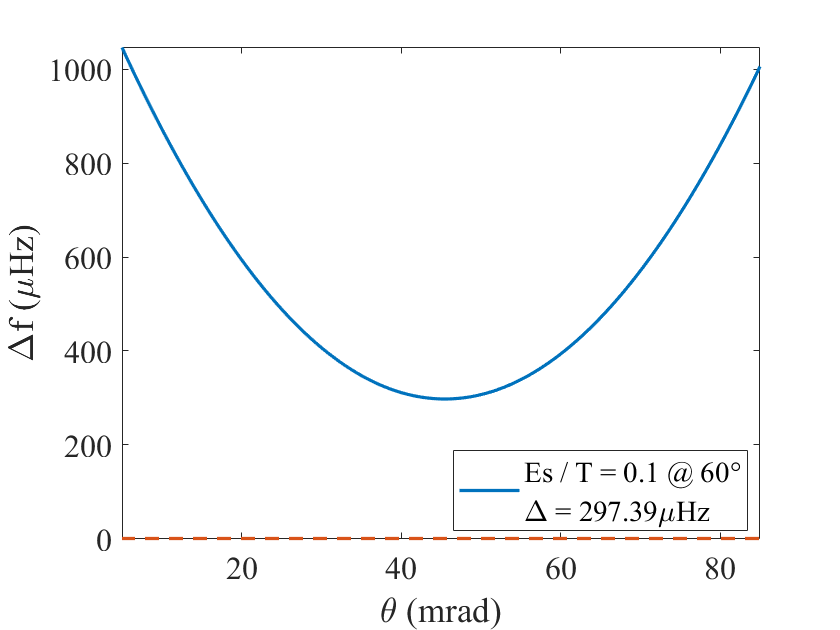


clear all;
close all;

save_data = 0;
maindir = '\\Artemis-pc\Data\2026-08-27\';

F=5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');

Bz = 123;   % mHz
mrad = [-4:0.02:4]*10+45;
theta_x = (mrad)*1e-3;
Tz = 1.1*Bz;
TE = 0.1*Tz;
theta_E = 60*pi/180;   % degree

for k = 1:length(theta_x)
    Ham0 = Bz*sigmaz + 0*Bz*(sigmax+0*sigmay) + ...
        Tz*sigmaz^2;
    Ham1 = Bz*(sigmaz + theta_x(k)*sigmax)/sqrt(1+theta_x(k)^2) + ...
        Tz*sigmaz^2 + ...
        TE*(cos(theta_E)*sigmaz+sin(theta_E)*sigmax)^2;
    
    [vec0, eig0] = eig(Ham0);
    [vec1, eig1] = eig(Ham1);
    
    diff0 = eig0(5,5)-eig0(6,6);
    diff1 = eig1(5,5)-eig1(6,6);
    df(k) = (diff1-diff0)*1.4*1e3;   % uHz
    dR(k) = (diff1-diff0)/(Bz*5)*0.726;
end

f1 = figure; hold on;
plot(mrad,df,'LineWidth',1.6);
plot([min(mrad) max(mrad)],[0 0],'--',...
    'LineWidth',1.6);
xlim([min(mrad) max(mrad)]);
ymin = min([-1 min(df)-1]);
ymax = max([1 max(df)+1]);
ylim([ymin ymax]);
xlabel('\theta (mrad)');
ylabel('\Deltaf (\muHz)');
legend(['Es / T = ',num2str(TE/Tz),' @ ',num2str(theta_E*180/pi),'\circ', ...
    '\newline','\Delta = ',num2str(min(df),'%.2f'),'\muHz'],...
    '','Location','best');

set(f1,'Visible','on');
set(gca,'FontName','times new roman','FontSize',16);
box on;


filename = ['Es',num2str(round(TE/Tz)),'@',num2str(theta_E*180/pi)];
if save_data == 1
    savefig(f1,[maindir,filename,'.fig']);
    saveas(f1,[maindir,filename,'.png']);
    %
    save([maindir,filename,'.mat']);
end
